`  BETA DISTRIBUTION`

`% % % % % % % % % % % % % % % % % % % % % % % % `

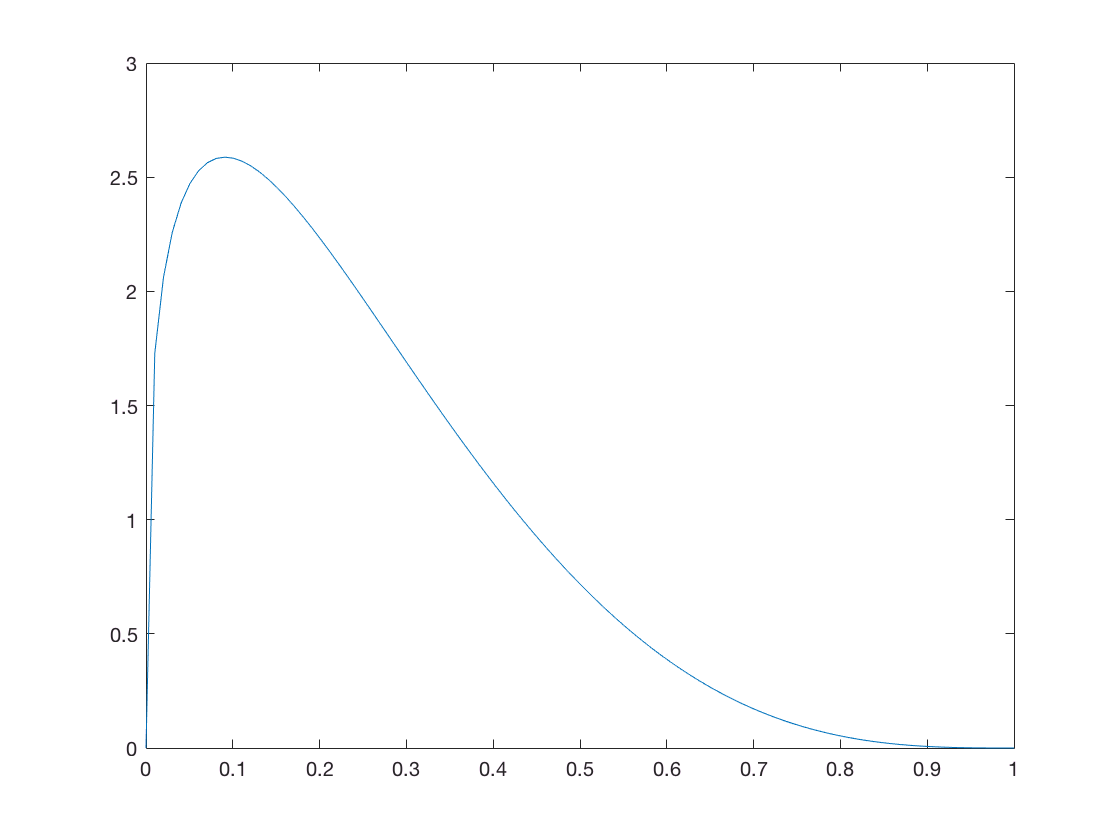

xx = linspace(0,1,100);
plot(xx,betapdf(xx,1.3,4))

## gamma distribution

nSamples = 1e6;

Jbar = 2;
tau = 2;

shape = Jbar/tau;
scale = tau;

blah = gamrnd(shape,scale,[1 nSamples]);

## create model fit datat psychometric fn

clear all

filelocation = 'results/vss-dec2016/txt/';
load([filelocation 'modelfits.mat'])
subjids = {'ALM','DR','EN','MR'};
exptype = 'Delay';
model = 2;
modelstr = sprintf('model%d',model);

nSubj = length(subjids);
deltaVec = 2.5:5:87.5;

isubj = 3;
% for isubj = 1:nSubj
subjid = subjids{isubj};
bfp = fits.(modelstr).(exptype).bfpMat(isubj,:)

bfp =    19.7357   30.8452   62.2688    0.0005


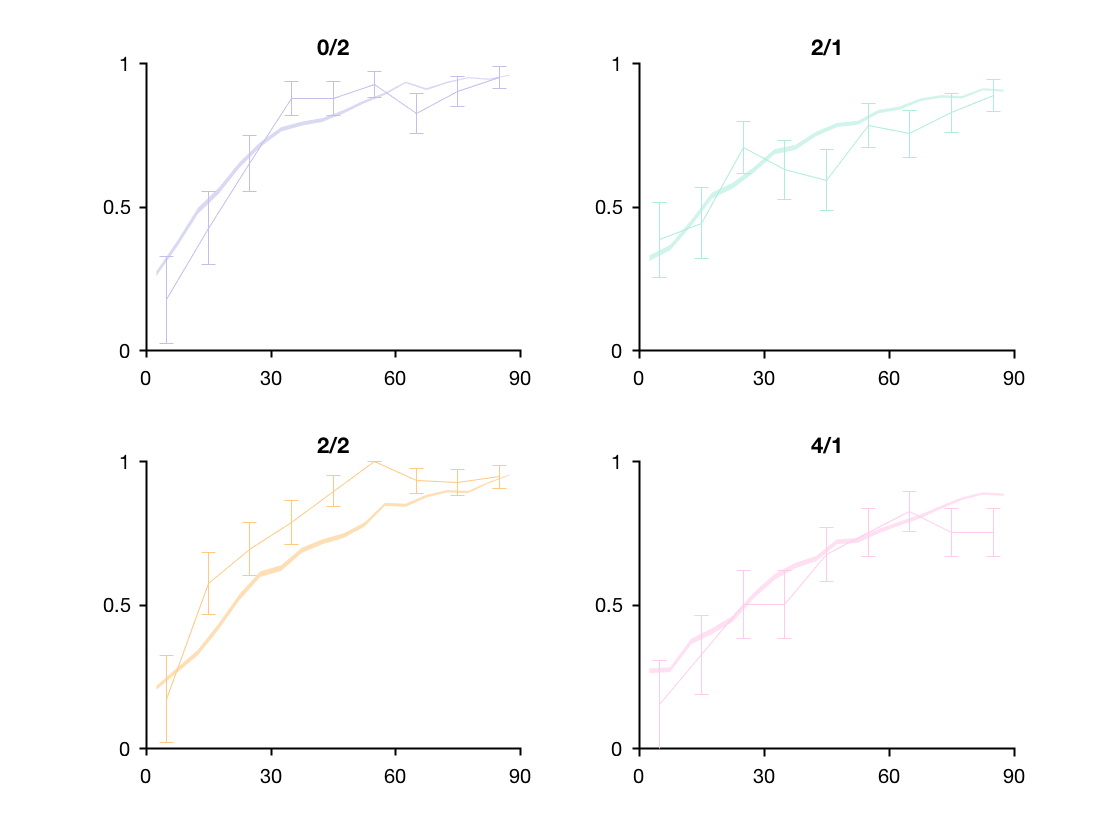

if bfp(4) == 0
    bfp(4) = 1e-6;
end

X = []; % data in luigiform
Nsamples = 1000; % default if empty

[~,prmat,X] = AhyBCL_datalikeall(bfp,X,model,Nsamples);

% plot psychometric function
figure;
hold on;
colors = aspencolors(4,'pastel');%['b'; 'y'; 'g'; 'r'];
condlegendd = {'0/2', '2/1','2/2','4/1'};
for icond = 1:4
    subplot(2,2,icond)
    plot_psychometricfunction({subjid},exptype,icond); % plot real data
    pc = prmat{icond}(:,1)';
    pc_std = pc.*(1-pc)./24;
    plot_summaryfit(deltaVec,[],[],pc,pc_std,colors(icond,:),colors(icond,:));
    title(condlegendd{icond})
    axis([0 90 0 1])
    ax = gca;
    ax.XTick = [0 30 60 90];
    ax.YTick = 0:.5:1;
    %     fill([deltaVec fliplr(deltaVec)],[pc-pc_std fliplr(pc + pc_std)],colors(icond,:))
end

## average plot

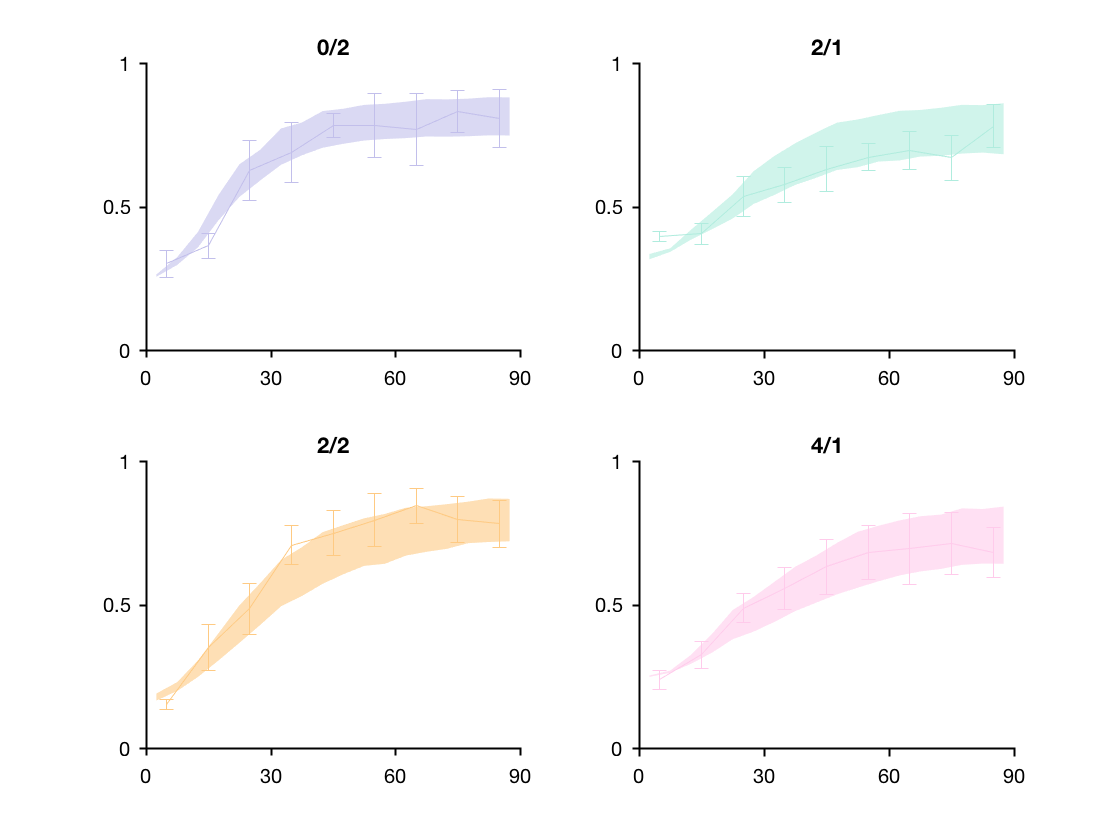

clear all

load('modelfits.mat')
subjids = {'ALM','DR','EN','MR'};
exptype = 'Delay';
model = 2;

modelstr = sprintf('model%d',model);
nSubj = length(subjids);
deltaVec = 2.5:5:87.5;

PRMat = cell(1,4);
for isubj = 1:nSubj
    subjid = subjids{isubj};
    bfp = fits.(modelstr).(exptype).bfpMat(isubj,:);
    if bfp(4) == 0
        bfp(4) = 1e-6;
    end
    
    X = []; % data in luigiform
    Nsamples = 1000; % default if empty
    
    [~,prmat,X] = AhyBCL_datalikeall(bfp,X,model,Nsamples);
    
    PRMat = cellfun(@(x,y) [x;y(:,1)'],PRMat,prmat,'UniformOutput',false);
    
end
mean_mod = cellfun(@mean,PRMat,'UniformOutput',false);
sem_mod = cellfun(@(x) std(x)/sqrt(size(x,1)),PRMat,'UniformOutput',false);
mean_mod= reshape(cell2mat(mean_mod),[18 4])';
sem_mod = reshape(cell2mat(sem_mod),[18 4])';

% plot psychometric function
figure;
hold on;
colors = aspencolors(4,'pastel');%['b'; 'y'; 'g'; 'r'];
condlegendd = {'0/2', '2/1','2/2','4/1'};
for icond = 1:4
    
    subplot(2,2,icond)
    plot_psychometricfunction(subjids,exptype,icond); % plot real data
    
    plot_summaryfit(deltaVec,[],[],mean_mod(icond,:),sem_mod(icond,:),colors(icond,:),colors(icond,:));
    title(condlegendd{icond})
    axis([0 90 0 1])
    ax = gca;
    ax.XTick = [0 30 60 90];
    ax.YTick = 0:.5:1;
    %     fill([deltaVec fliplr(deltaVec)],[pc-pc_std fliplr(pc + pc_std)],colors(icond,:))
end

trying to see trade off between difference in reliabilties and how many trials are necessary to tell them apart

EXPERIMENT

four conditions: 

- all high reliability (change in high reliability stimulus)

- all low reliability (change in low reliability stimulus)

- half high and half low reliablity (ahcne in high reliability stimulus)

- half high and half low reliability (change in low reliability stimulus)

currently, each condition has around 360 trials. 20 trials per magnitude of change 2.5:5:87.5. 

data is set up to be 18 x 3, where each row corresponds to magnitude of change, and each column corresponds to the number of correct, number of incorrect at correct relability, and number of incorrect at incorrect reliability

PARAMETERS: Jbar (low), Jbar (high), tau, lapse

GOALS:

- to see if i can decrease trial size (decrease number of all high/low trials). how many trials necessary to reliably estimate uncertainty parameters?

- see if estimating parameters from homogeneous conditions are better alone than using homogeneous and heterogeneous trials to estimate parameters (related: think about other ways to model the data. first do homogeneous, then fit hetero w/ fitted parameters? with new paameters?)

- see how increasing the difference between the two reliability condiditions affects ability to tell the two models apart. 

- see how number of trials affects ability to tell two models apart

% parameters
model = 1;
theta = [3 8 5 0.25];
Nsamples = 1000;

% generate fake data just homogeneous
X{1}.Nset1 = 0; X{1}.Nset2 = 4; X{1}.Cset = 2;
X{2}.Nset1 = 4; X{2}.Nset2 = 0; X{2}.Cset = 1;
for iCnd = 1:numel(X); X{iCnd}.Rmat = []; end
[loglike,prmat,X] = AhyBCL_datalikeall(theta,X,model,Nsamples)

% fit data